## Preprocessing

*Toolboxes developed by MIR Lab: Jyh-Shing Roger Jang, "Utility Toolbox", available from the link at the*

*author's homepage at "http://mirlab.org/jang"*

MIR Lab MATLAB Toolboxes:

    • Utility Toolbox - commonly used utility functions (required for following toolboxes)

    • Machine Learning Toolbox - provides a number of machine learning functions

    • SAP (Speech and Audio Processing) Toolbox - MATLAB functions for speech and audio signal

    processing

%Toolboxes
addpath C:\Users\jackg\matlab\datasets\genres\
addpath C:\Users\jackg\matlab\toolboxes\utility\
addpath C:\Users\jackg\matlab\toolboxes\sap\
addpath C:\Users\jackg\matlab\toolboxes\machineLearning\
addpath C:\Users\jackg\matlab\toolboxes\machineLearning\externalTool\libsvm-3.21\matlab\ % For using SVM classifier
%Compatability check
fprintf('Platform: %s\n', computer);

Platform: PCWIN64


fprintf('MATLAB version: %s\n', version);

MATLAB version: 9.11.0.1809720 (R2021b) Update 1


fprintf('Script starts at %s\n', char(datetime));

Script starts at 08-Dec-2021 23:05:19


scriptStartTime=tic; % Timing for the whole script

## Dataset Collection

*Class labels: Blues, Classical, Hiphop, Jazz, Reggae, Rock, Country, Disco, Metal, Pop*

    • The audio files have extensions of "wav"

    • Files are organized for easy parsing, with a subfolder for each class

%Collect all the audio files from corpus directory
auDir='C:/Users/jackg/matlab/datasets/genres';
opt=mmDataCollect('defaultOpt');
opt.extName='wav';
auSet=mmDataCollect(auDir, opt, 1)

auSet = 1000×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum
    path
    parentDir
    class
    classId


Fields: name, folder, date, bytes, isdir, datenum, path, parentDir.

## Feature Extraction

*Extract the corresponding feature vector for each audio sample for classification*

Using basic acoustic features: Mel-frequency Cepstral Coefficients

    • The function mgcFeaExtract.m is used, which obtains the Mel-frequency Ceptstral Coefficients

    • Entire dataset is put into single variable "ds" for classifier construction and evaluation

The extracted features are based on MFCC's statistics including mean, std, and max along each dimenstion

    • MFCC has 39 dimensions

    • Extracted file-based features has 156 dimensions

if ~exist('ds.mat', 'file')
 myTic=tic;
 opt=dsCreateFromMm('defaultOpt');
 opt.auFeaFcn=@mgcFeaExtract; % Function for feature extraction
 opt.auFeaOpt=feval(opt.auFeaFcn, 'defaultOpt'); % Feature options
 opt.auEpdFcn=''; % No need to do endpoint detection
 ds=dsCreateFromMm(auSet, opt, 1);
 fprintf('Time for feature extraction over %d files = %g sec\n', length(auSet), toc(myTic));
 fprintf('Saving ds.mat...\n');
 save ds ds
else
 fprintf('Loading ds.mat...\n');
 load ds.mat
end

Loading ds.mat...


**Plot the file-based features for one audio file:**

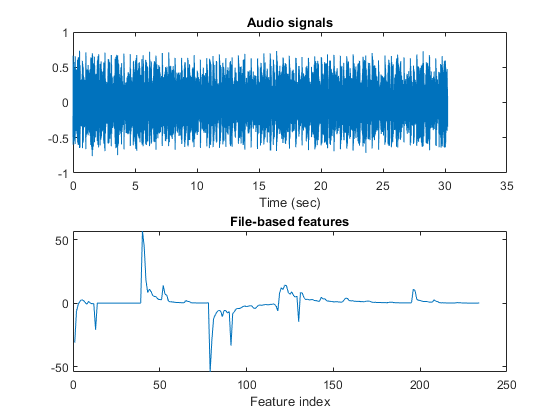

auFile=[auDir, '/disco/disco.00001.wav'];
figure; mgcFeaExtract(auFile, [], 1);

## Dataset vizualization

*All relevant information is now stored in "ds", Machine Learning Toolbox is used for data visualization*

*and classification*

Size of each class:

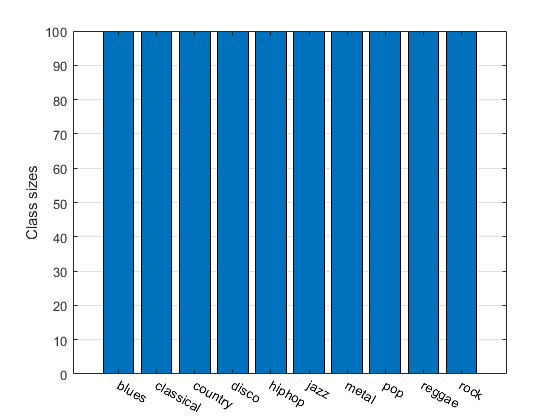

156 features
1000 instances
10 classes


figure;
[classSize, classLabel]=dsClassSize(ds, 1);

**Plot the range of features:**

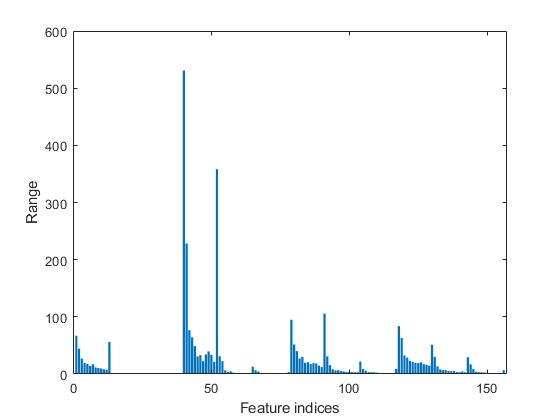

figure; dsRangePlot(ds);

**Plot of the feature vectors within each class:**

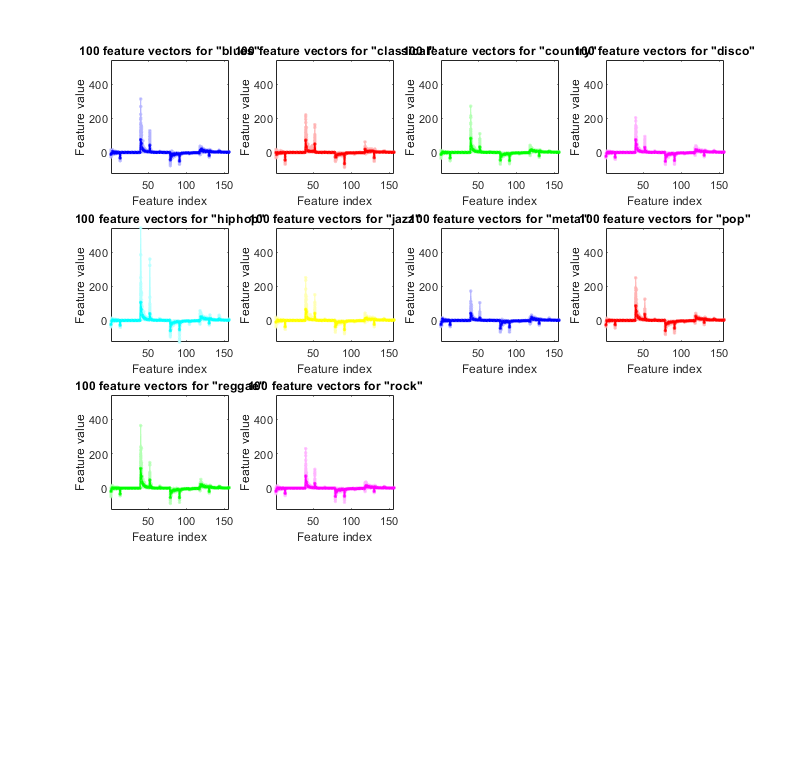

figure; dsFeaVecPlot(ds); figEnlarge;

## Dimensionality Reduction: "ds" and "ds2"

The dimension of the feature vector is large (156 dimensions), we will perform dimensionality reduction via PCA

(principal component analysis)

## Cumulative variance given the descending PCA eigenvalues:

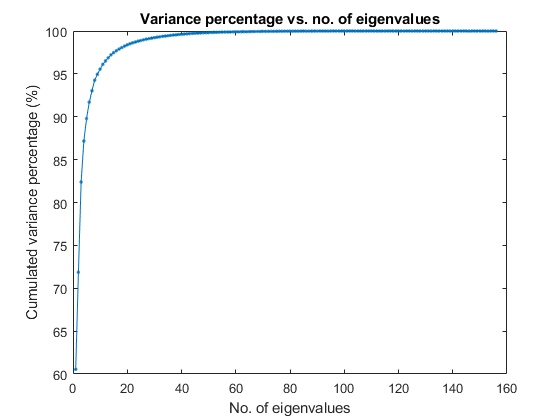

[input2, eigVec, eigValue]=pca(ds.input);
cumVar=cumsum(eigValue);
cumVarPercent=cumVar/cumVar(end)*100;
figure; plot(cumVarPercent, '.-');
xlabel('No. of eigenvalues');
ylabel('Cumulated variance percentage (%)');
title('Variance percentage vs. no. of eigenvalues');

Threshold to retain dimensionality is 95% for cumulative variance percentage

cumVarTh=95;
index=find(cumVarPercent>cumVarTh);
newDim=index(1);
ds2=ds; %reduced dimensionality data
ds2.input=input2(1:newDim, :);
fprintf('Reduce the dimensionality to %d to keep %g%% cumulative variance via PCA.\n', newDim, cumVarTh);

Reduce the dimensionality to 10 to keep 95% cumulative variance via PCA.


*Classification will be performed using both "ds" (156 dimensions) and ds2 (reduced dimensionality data)*

## Using LDA, project original dataset into 2-D space to visualize distribution of dataset:

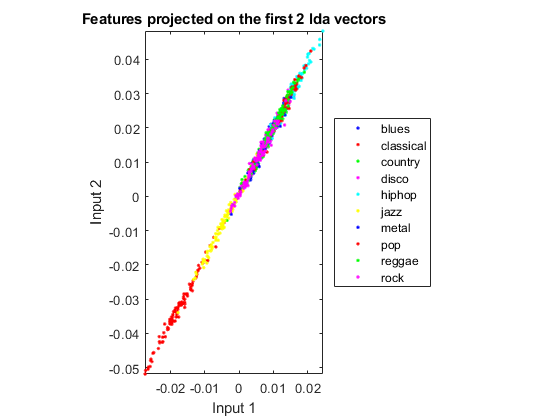

ds2d=lda(ds);
ds2d.input=ds2d.input(1:2, :);
figure; dsScatterPlot(ds2d); xlabel('Input 1'); ylabel('Input 2');
title('Features projected on the first 2 lda vectors');
legend('Location',"eastoutside",'Orientation',"vertical");

## Classification

### k-Nearest Neighbor Classifier

Using original dataset (no dimensionality reduction):

[rr, ~]=knncLoo(ds);
ds0=ds; ds0.input=inputNormalize(ds0.input);
[rr0, computed]=knncLoo(ds0);
fprintf('Recognition Rate=%g%% for original ds\n', rr*100); fprintf('Recognition Rate=%g%% for ds after input normalization\n', rr0*100);

Recognition Rate=57.6% for original ds
Recognition Rate=64.9% for ds after input normalization


## Using reduced dataset (PCA dimensionality reduction):

[rr, ~]=knncLoo(ds2);
ds0=ds2; ds0.input=inputNormalize(ds0.input);
[rr0, computed]=knncLoo(ds0);
fprintf('Recognition Rate=%g%% for dimensionality reduced ds\n', rr*100); fprintf('Recognition Rate=%g%% for ds after input normalization\n', rr0*100);

Recognition Rate=52.3% for dimensionality reduced ds
Recognition Rate=55.1% for ds after input normalization


## SVM

Use function mgcOptSet.m to put all music genere classification options in single file

Fold = 100/1000
Fold = 200/1000
Fold = 300/1000
Fold = 400/1000
Fold = 500/1000
Fold = 600/1000
Fold = 700/1000
Fold = 800/1000
Fold = 900/1000
Fold = 1000/1000
Training RR=99.01%, Validating RR=77.00%, classifier=svmc, no. of folds=1000


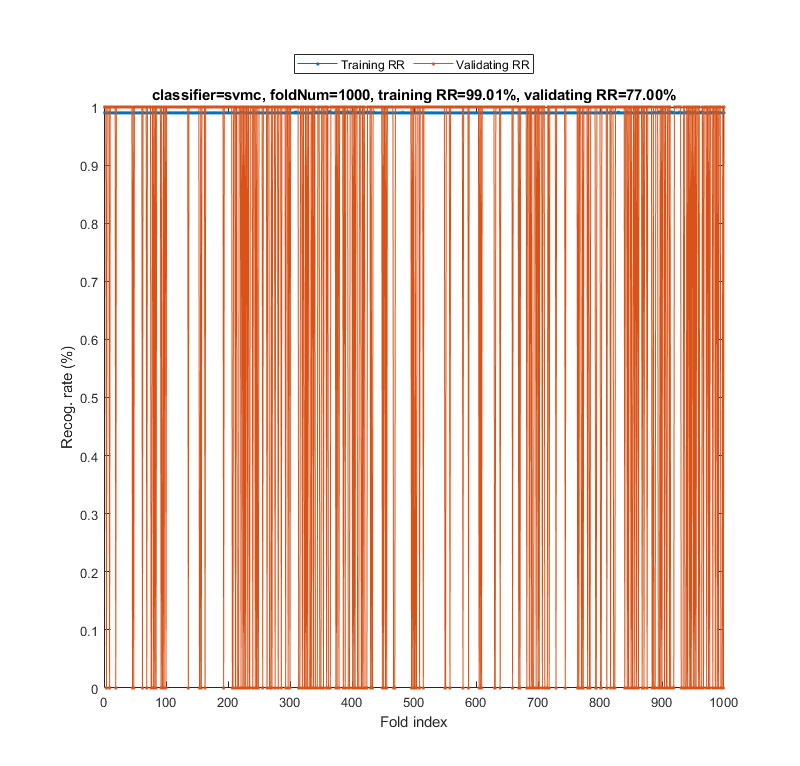

myTic=tic;
mgcOpt=mgcOptSet;
if mgcOpt.useInputNormalize, ds.input=inputNormalize(ds.input); end % Input normalization
cvPrm=crossValidate('defaultOpt');
cvPrm.foldNum=mgcOpt.foldNum;
cvPrm.classifier=mgcOpt.classifier;
plotOpt=1;
figure; [tRrMean, vRrMean, tRr, vRr, computedClass]=crossValidate(ds, cvPrm, plotOpt); figEnlarge;

fprintf('Time for cross-validation = %g sec\n', toc(myTic));

Time for cross-validation = 385.849 sec


## Plot the confusion matrix:

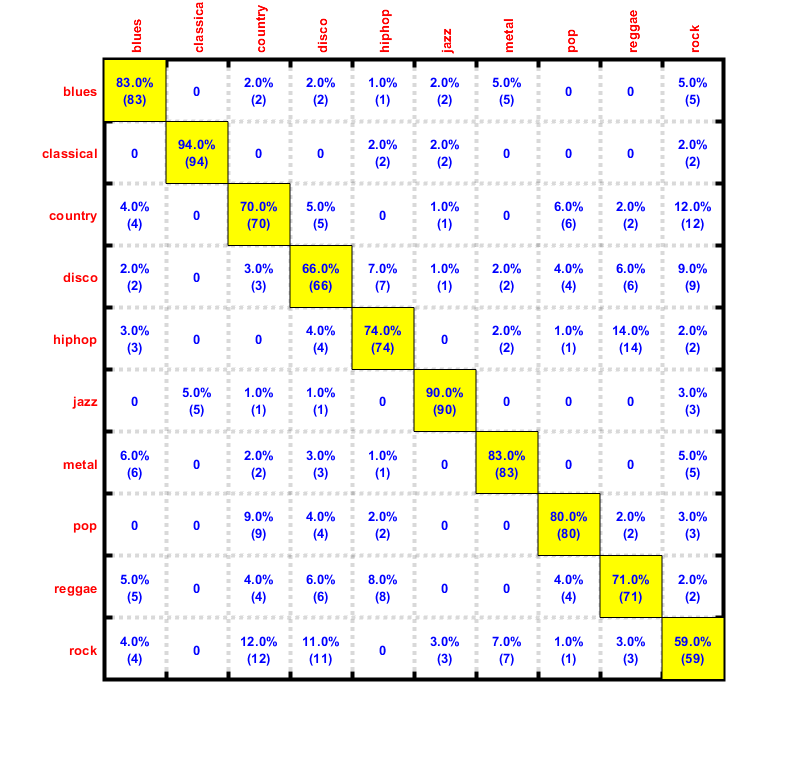

for i=1:length(computedClass)
 computed(i)=computedClass{i};
end
desired=ds.output;
confMat = confMatGet(desired, computed);
cmOpt=confMatPlot('defaultOpt');
cmOpt.className=ds.outputName;
confMatPlot(confMat, cmOpt); figEnlarge;

## Phase II

Download data in new format

dataURL = 'http://opihi.cs.uvic.ca/sound/genres.tar.gz';
gunzip(dataURL,tempdir)                       % creates genres.tar in tempdir
untar(fullfile(tempdir,'genres.tar'),tempdir) % creates genres folder

## Wavelet Scattering Framework

sn = waveletScattering('SignalLength',2^19,'SamplingFrequency',22050,...
    'InvarianceScale',0.5);

## Obtain and Plot Scaling Filter

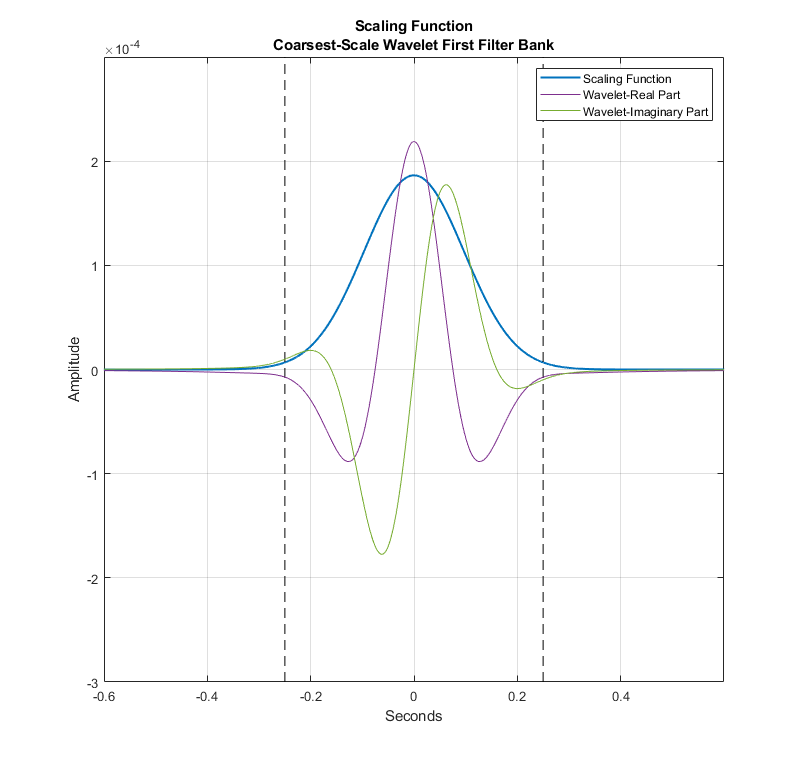

[fb,f,filterparams] = filterbank(sn);
phi = ifftshift(ifft(fb{1}.phift));
psiL1 = ifftshift(ifft(fb{2}.psift(:,end)));
dt = 1/22050;
time = -2^18*dt:dt:2^18*dt-dt;
scalplt = plot(time,phi,'linewidth',1.5);
hold on
grid on
ylimits = [-3e-4 3e-4];
ylim(ylimits)
plot([-0.25 -0.25],ylimits,'k--')
plot([0.25 0.25],ylimits,'k--')
xlim([-0.6 0.6])
xlabel('Seconds')
ylabel('Amplitude')
wavplt = plot(time,[real(psiL1) imag(psiL1)]);
legend([scalplt wavplt(1) wavplt(2)],...
    {'Scaling Function','Wavelet-Real Part','Wavelet-Imaginary Part'})
title({'Scaling Function';'Coarsest-Scale Wavelet First Filter Bank'})
hold off

## Audio Datastore

location = fullfile(tempdir,'genres');
ads = audioDatastore(location,'IncludeSubFolders',true,...
    'LabelSource','foldernames');
countEachLabel(ads)

ans = 10×2 table
      Label      Count
    _________    _____

    blues         100 
    classical     100 
    country       100 
    disco         100 
    hiphop        100 
    jazz          100 
    metal         100 
    pop           100 
    reggae        100 
    rock          100 


## Training and Test Sets

rng(100)
ads = shuffle(ads);
[adsTrain,adsTest] = splitEachLabel(ads,0.8);
countEachLabel(adsTrain)

ans = 10×2 table
      Label      Count
    _________    _____

    blues         80  
    classical     80  
    country       80  
    disco         80  
    hiphop        80  
    jazz          80  
    metal         80  
    pop           80  
    reggae        80  
    rock          80  


countEachLabel(adsTest)

ans = 10×2 table
      Label      Count
    _________    _____

    blues         20  
    classical     20  
    country       20  
    disco         20  
    hiphop        20  
    jazz          20  
    metal         20  
    pop           20  
    reggae        20  
    rock          20  


## Obtain Scattering Features

N = 2^19;
batchsize = 64;
scTrain = [];
useGPU = true; % Set to true to use the GPU

while hasdata(adsTrain)
    sc = helperbatchscatfeatures(adsTrain,sn,N,batchsize,useGPU);
    scTrain = cat(3,scTrain,sc);
end

numTimeWindows = size(scTrain,2);

scTest = [];

while hasdata(adsTest)
   sc = helperbatchscatfeatures(adsTest,sn,N,batchsize,useGPU);
   scTest = cat(3,scTest,sc); 
end

## Reshape Features

[~,npaths] = sn.paths();
Npaths = sum(npaths);
TrainFeatures = permute(scTrain,[2 3 1]);
TrainFeatures = reshape(TrainFeatures,[],Npaths);
TestFeatures = permute(scTest,[2 3 1]);
TestFeatures = reshape(TestFeatures,[],Npaths);

## Create Genre Labels for Windows in Wavelet Feature Matrix

%Training Data
trainLabels = adsTrain.Labels;
numTrainSignals = numel(trainLabels);
trainLabels = repmat(trainLabels,1,numTimeWindows);
trainLabels = reshape(trainLabels',numTrainSignals*numTimeWindows,1);
%Test Data
testLabels = adsTest.Labels;
numTestSignals = numel(testLabels);
testLabels = repmat(testLabels,1,numTimeWindows);
testLabels = reshape(testLabels',numTestSignals*numTimeWindows,1);

## Fit SVM to Training Data

template = templateSVM(...
    'KernelFunction', 'polynomial', ...
    'PolynomialOrder', 3, ...
    'KernelScale', 'auto', ...
    'BoxConstraint', 1, ...
    'Standardize', true);
Classes = {'blues','classical','country','disco','hiphop','jazz',...
    'metal','pop','reggae','rock'};
classificationSVM = fitcecoc(...
    TrainFeatures, ...
    trainLabels, ...
    'Learners', template, ...
    'Coding', 'onevsone','ClassNames',categorical(Classes));

## Test Set Prediction

predLabels = predict(classificationSVM,TestFeatures);
[TestVotes,TestCounts] = helperMajorityVote(predLabels,adsTest.Labels,categorical(Classes));
testAccuracy = sum(eq(TestVotes,adsTest.Labels))/numTestSignals*100

testAccuracy = 87.5000

## Confusion Matrix

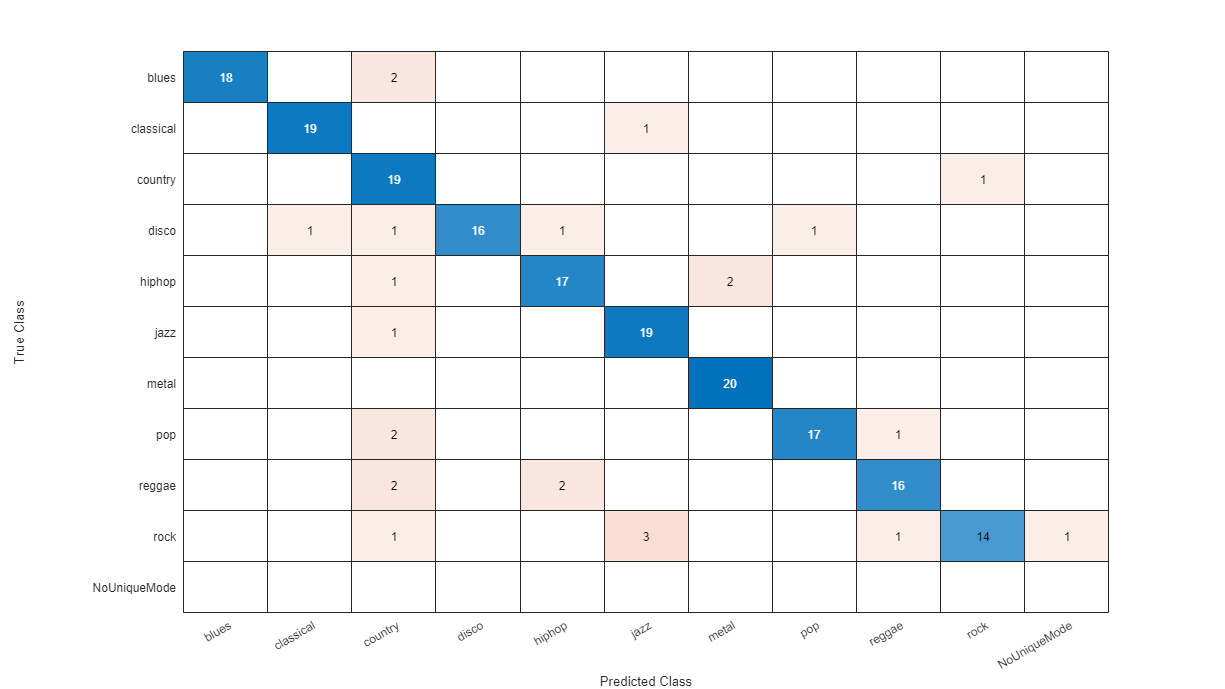

cm = confusionchart(adsTest.Labels,TestVotes);

## Plot Percentage Correct

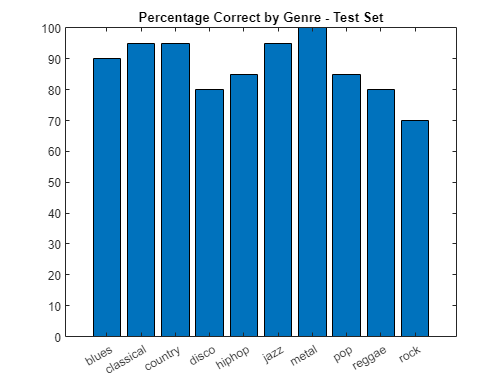

cmat = cm.NormalizedValues;
cmat(end,:) = [];
genreAccuracy = diag(cmat)./20*100;
figure
bar(genreAccuracy)
set(gca,'XTickLabels',Classes)
xtickangle(gca,30)
title('Percentage Correct by Genre - Test Set')

## Supporting Functions

type helperMajorityVote

function [ClassVotes,ClassCounts] = helperMajorityVote(predLabels,origLabels,classes)
% This function is in support of wavelet scattering examples only. It may
% change or be removed in a future release.

% Make categorical arrays if the labels are not already categorical
predLabels = categorical(predLabels);
origLabels = categorical(origLabels);
% Expects both predLabels and origLabels to be categorical vectors
Npred = numel(predLabels);
Norig = numel(origLabels);
Nwin = Npred/Norig;
predLabels = reshape(predLabels,Nwin,Norig);
ClassCounts = countcats(predLabels);
[mxcount,idx] = max(ClassCounts);
ClassVotes = classes(idx);
% Check for any ties in the maximum values and ensure they are marked as
% error if the mode occurs more than once
tmpsum = sum(ClassCounts == mxcount);
ClassVotes(tmpsum > 1) = categorical({'NoUniqueMode'});
ClassVotes = ClassVotes(:);



function sc = helperbatchscatfeatures(ds,sn,N,batchsize,useGPU)
% This function is only intended to support examples in the Wavelet
% Toolbox. It may be changed or removed in a future release.

% Read batch of data from audio datastore
batch = helperReadBatch(ds,N,batchsize);
if useGPU
    batch = gpuArray(batch);
end

% Obtain scattering features
S = sn.featureMatrix(batch,'transform','log');
gather(batch);
S = gather(S);
    
% Subsample the features
sc = S(:,1:6:end,:);
end

function batchout = helperReadBatch(ds,N,batchsize)
% This function is only in support of Wavelet Toolbox examples. It may
% change or be removed in a future release.
%
% batchout = readReadBatch(ds,N,batchsize) where ds is the Datastore and
%   ds is the Datastore
%   batchsize is the batchsize

kk = 1;

while(hasdata(ds)) && kk <= batchsize
    tmpRead = read(ds);
    batchout(:,kk) = cast(tmpRead(1:N),'single'); %#ok<AGROW>
    kk = kk+1;
end

end